# Working with Neighborhoods

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

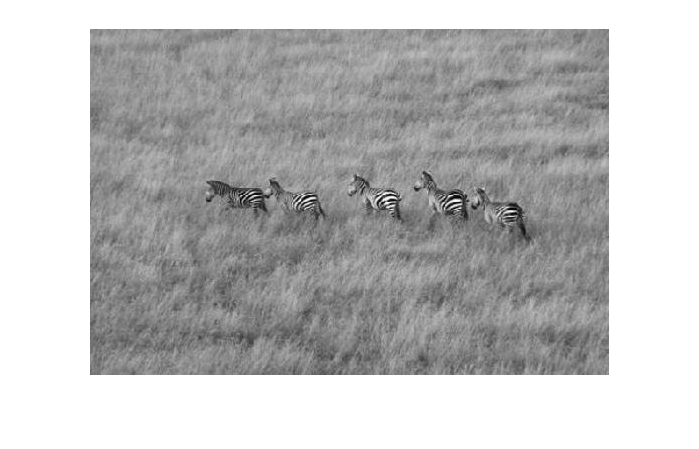

zebras = imread("./images/zebras.jpg");
zebras = im2gray(zebras);
imshow(zebras)

## Task 1

The image has already been converted to grayscale for you in the starter code.

Use `rangefilt` to apply a range filter to an image.

`imRNG` `=` `rangefilt``(``im``)`

By default, `rangefilt` will use a 3-by-3 filter.

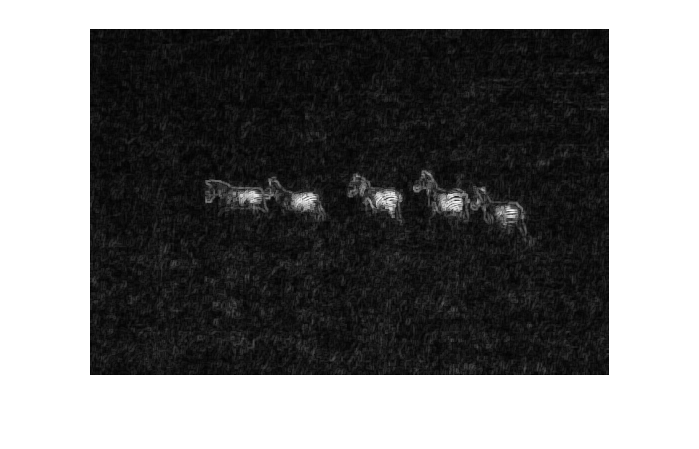

zebraRNG = rangefilt(zebras);
imshow(zebraRNG)

## Task 2

The default 3-by-3 neighborhood was a bit too small. You can see some dark spots in the zebras where the neighborhood was completely contained within a stripe and did not detect variation.

You can create an *n*-by-*n* neighborhood with the `true` function.

`nH` `=` `true``(``n``)``;`

So, `true``(``3``)` would create the default neighborhood, a 3-by-3 matrix of `1`s.

nHood = true(15);

## Task 3

Use `rangefilt` to apply a range filter to an image.

`imRNG` `=` `rangefilt``(``im``,``nH``)`

`im` is the image, and `nH` is a logical matrix specifying which neighboring pixels to include in the range calculation.

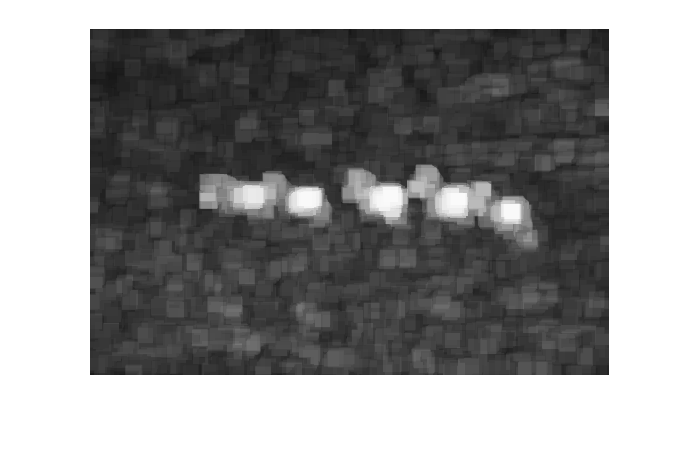

zebraRNG = rangefilt(zebras, nHood);
imshow(zebraRNG)

## Task 4

A 15-by-15 neighborhood was too large. You can see that the bright areas identifying the zebras are too clunky. This would result in an over-segmentation.

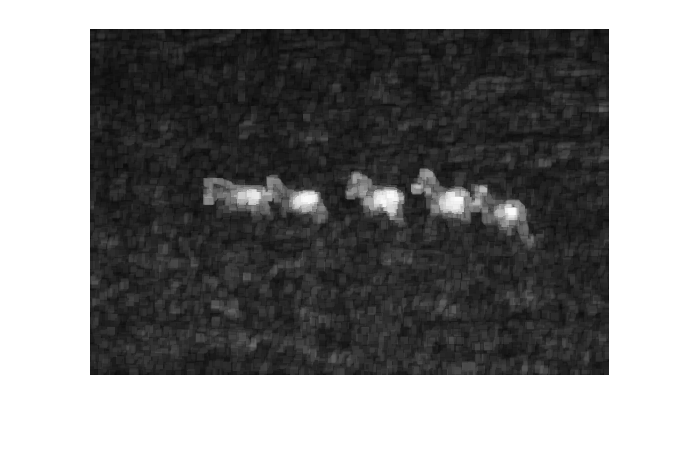

nHood = true(7); 
zebraRNG = rangefilt(zebras, nHood);
imshow(zebraRNG)

## Task 5

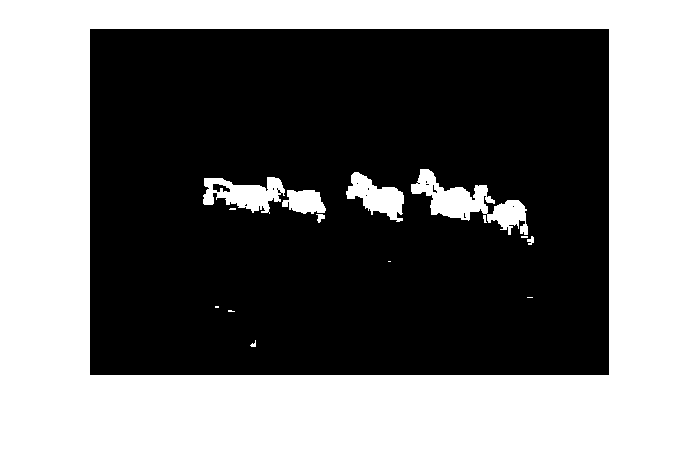

zebraBW = imbinarize(zebraRNG);
imshow(zebraBW)